clear all
rng(1)

nspec = 3;
nm = 2;
np = 2;
p_length = 101;

nrep = 50;
polys_diff = zeros(1, nrep);
max_row_diff = zeros(1, nrep);
sd_res1 = zeros(1, nrep);
ncoex_vec = zeros(1, nrep);

for k = 1:nrep
    k
    polys = zeros(np, nm);
    for i = 1:np
        polys(i, :) = create_poly(p_length, nm);
    end
    
    cons_traits_mono = rand(nspec, nm);
    cons_traits_mono = cons_traits_mono ./ sum(cons_traits_mono, 2);
    
    C = zeros(nspec, np);
    for i = 1:nspec
        C(i, :) = sum((polys' .* cons_traits_mono(i, :)')', 2);
    end
    
    C = (C * nm) / 50;
    
    params.nspec = nspec;
    params.np = np;
    params.alpha = 0 * ones(nspec, 1);
    params.r = 500 * ones(np, 1);
    params.K = ones(np, 1);
    params.m = 0.2 * ones(nspec, 1);
    params.C = C;
    
    init_abuns = ones(1, params.nspec) * 5;
    init_res = ones(1, params.np) * 5;
    init_state = [init_abuns, init_res];
    
    tspan = [0 10000];
    [t, sim] = ode45(@(t, y) macarthur_eqns(t, y, params), tspan, init_state);
    
    eql = sim(end, :);
    eql_abuns = eql(1:nspec);
    num_coexist = sum(eql_abuns > 1);
    ncoex_vec(k) = num_coexist;
    asym = sum(polys(:,1) > 50);
    if asym == 1
        polys_diff(k) = 1;
    else
        polys_diff(k) = 0;
    end

    row_tots = sum(C,2);
    max2 = maxk(row_tots, 2);
    max_row_diff(k) = max2(1) - max2(2);
    sd_res1(k) = std(C(:,1));

end

k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 50

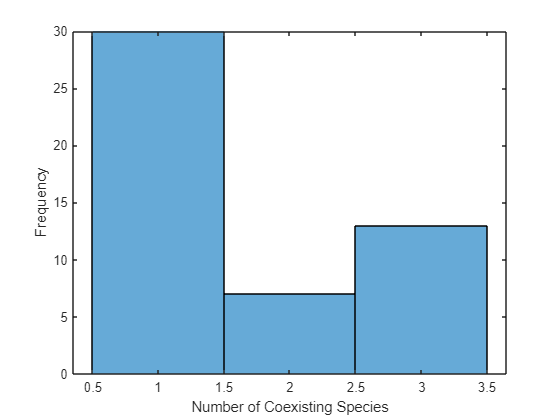


figure;
histogram(ncoex_vec);
xlabel('Number of Coexisting Species');
ylabel('Frequency');


max_row_diff

max_row_diff =     0.0320    0.2539    0.0992    0.0398    0.4106    0.1154    0.0370    0.0121    0.2460    0.0341    0.0381    0.0418    0.0016    0.0000    0.0325    0.0838    0.0182    0.0254    0.4604    0.2149    0.1112    0.1099    0.0989    0.0568    0.0300    0.0318    0.4021    0.0812    0.2293    0.1151    0.1169    0.1041    0.0652    0.0053    0.0064    0.0008    0.1287    0.0000    0.0296    0.0289         0    0.4087    0.0415    0.0412    0.0944    0.0000    0.0122    0.2004    0.2482    0.0152


ncoex_vec

ncoex_vec =      1     1     1     1     1     3     1     3     1     3     3     1     2     2     1     3     3     1     1     1     1     1     3     1     1     3     1     1     1     1     1     1     3     2     2     2     1     3     3     2     3     1     1     1     1     2     3     1     1     1


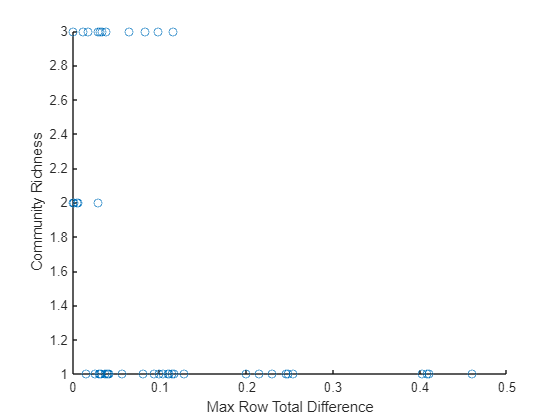


scatter(max_row_diff, ncoex_vec)
xlabel('Max Row Total Difference');
ylabel('Community Richness');

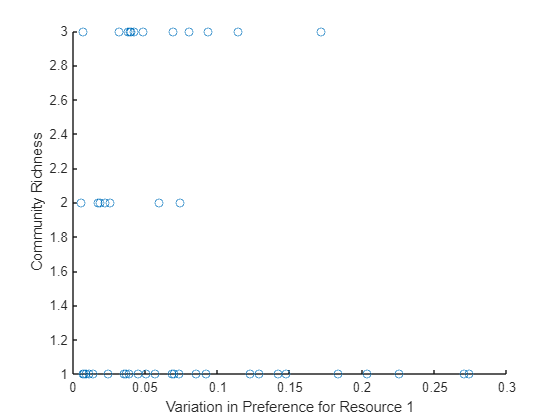

corr(max_row_diff(:), ncoex_vec(:))

scatter(sd_res1, ncoex_vec)
xlabel('Variation in Preference for Resource 1');
ylabel('Community Richness');

corr(sd_res1(:), ncoex_vec(:))

function counts = create_poly(p_length, nm)
    vec = randi(nm, 1, p_length);
    counts = histcounts(vec, 1:(nm+1));
end

function dydt = macarthur_eqns(~, state, params)
    N = state(1:params.nspec);
    R = state((params.nspec + 1):end);

    dNdt = params.alpha + N .* ((params.C * R) - params.m);
    dRdt = R .* (params.r .* (1 - R ./ params.K) - (params.C' * N));
    
    dydt = [dNdt; dRdt];
end